% basic parameter

% data length, fs, f
L = 153600; fs = 614.4e6; f = 10e6;
dt = 1/fs;
t = (1:L)'*dt;

rewrite = 1;

% generate data
q = 1; i = 1;
x = sin(2*pi*f*t)+cos(2*pi*f*t)*1j;
% figure;
% plot(t,abs(x));

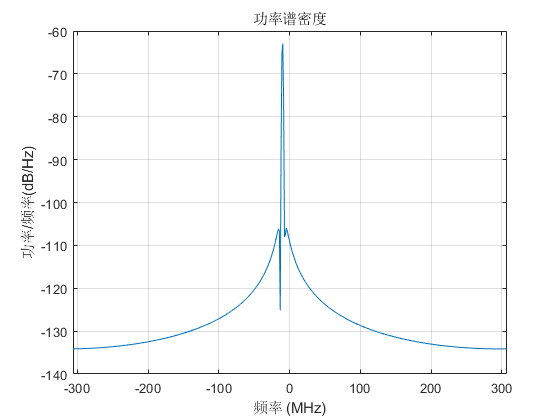

% plot the singal PSD
figure;
pwelch(x,2^9,[],[],614.4e6,'centered');

% figure;
% plot(real(x),imag(x),'.');

% senduit to SoC
send_RFSoC([],x,x);

% receive from SoC
[yBB,rxdata] = recv_RFSoC([]);

% plot the PSD
figure;
pwelch(yBB,2^9,[],[],614.4e6,'centered');
figure;
plot(t,abs(yBB));
hold on
plot(t,abs(x));
figure;
plot(real(yBB),imag(yBB),'.');
hold on
plot(real(x),imag(x),'.');

% both files should be uploaded manually
% receive from python and compare
rx_py = load('rx.mat');
yBB_py = rx_py.yBB;
figure;
pwelch([yBB yBB_py],2^12,[],[],614.4e6,'centered');
legend;

% check tx.amt
tx_py = load('tx.mat');
xBB_py = tx_py.ch2;
figure;
pwelch(xBB_py,2^12,[],[],614.4e6,'centered');
legend;

% rewrite the tx file
if rewrite
    x1 = sin(2*pi*2*f*t)-cos(2*pi*2*f*t)*1j;
    pwelch(x1,2^9,[],[],614.4e6,'centered');
    tx_py.ch2 = x1;
end
save('tx_new.mat','tx_py');
